# Introduction to MATLAB

## MATLAB Environment

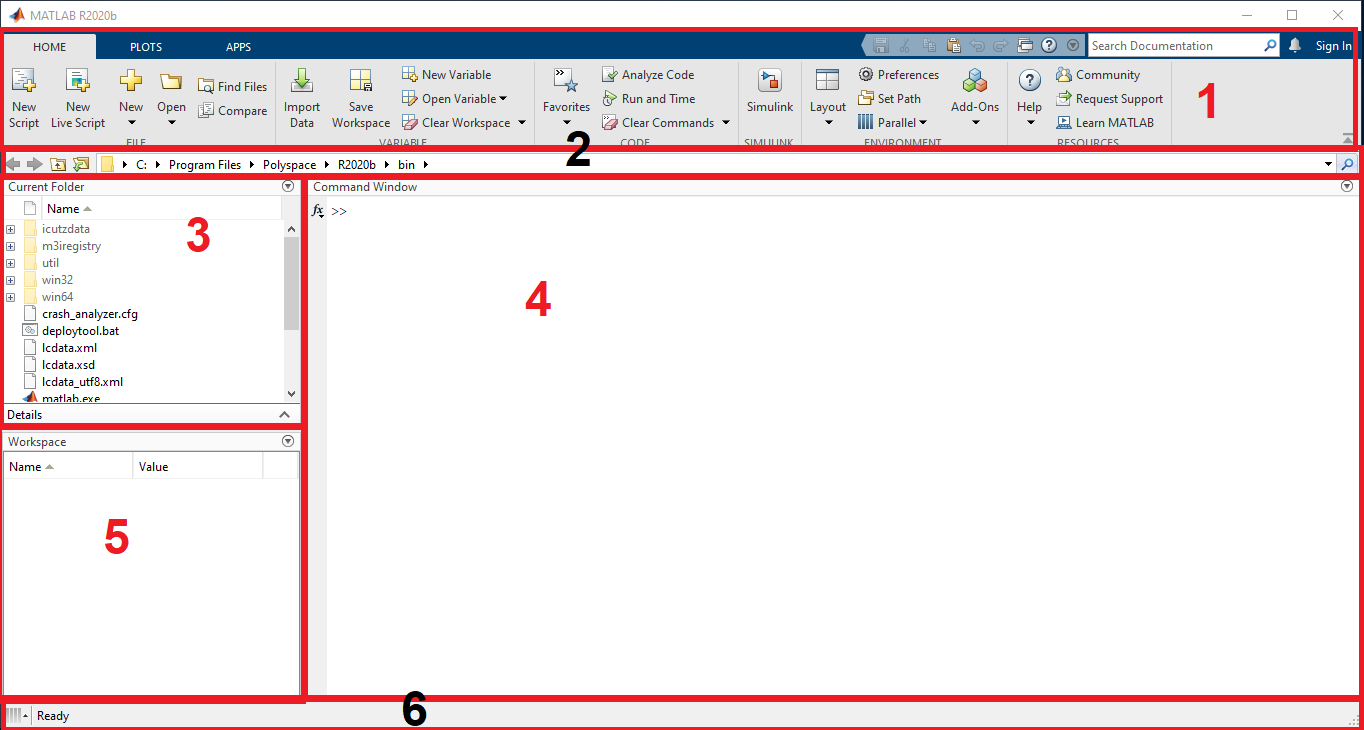

1- Toolbars

2- Directory

3- Current Folder

4- Command Window and command Prompt

5- Workspace: right click on the workspace bar -> choose columns -> check the **size** and **Class**

6- Statusbar: Ready, busy 

- Dock & Undock

- Command History

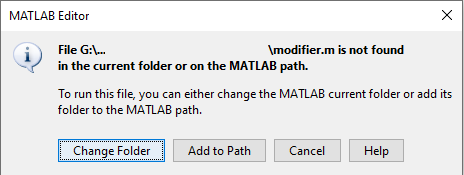

- Change Folder & Add to Path

## MATLAB Variables

- A variable name is a sequence of letters, numbers and underscores "_", **starting with a letter**.

- Although a variable name may have any length, MATLAB only recognises the first "few" characters. How many characters are recognised is specified by the Matlab command namelengthmax (which is typically 63). 

- Matlab uses = to assign a value to a variable. The left-hand-side of the = must be a valid variable name, while the right-hand-side must be a valid expression.

- MATLAB is case sensitive (as is Linux, but in contrast to Windows), so lower case letters are different from uppercase letters. Thus  x and  X    are **different** variables.

- You should not use a variable name that clashes with a constant, for example pi.

- Names cannot be MATLAB keywords, for example for, if, end, ... 

- How to add break point and debug?

p=2     % show the result

p = 2

q=3;    % does not show the result
disp(q);

     3



- semicolon at the end of the line

- use the percent (%) symbol to add comment

- use Ctrl+R to comment and Ctrl+T to Uncomment

### 1- Boolean

var_true = true;
var_false = false;


####     1.1- Logical Operators

    lgc_1 = var_true && var_false;      % AND
    lgc_2 = var_true || var_false;      % OR
    lgc_3 = ~var_true;                  % NOT
    

####     1.2- Comparison Operators

    comp_1 = p == q;        % equal
    comp_2 = p > q;         % greater
    comp_3 = p >= q;        % greater or equal
    comp_4 = p < q;         % smaller
    comp_5 = p <= q;        % smaller or equal
    comp_6 = p ~= q;        % not equal

### 2- double

`double` is the default numeric data type (class) in MATLAB, providing sufficient precision for most computational tasks. Numeric variables are automatically stored as 64-bit (8-byte) double-precision floating-point values.

val_1 = -2.3;                   % double 
val_2 = pi;                     % pi number
val_3 = 2.3e-3;                 % scientific notation (= 0.0023)
val_4 = NaN;                    % Not a number (i.e. 0/0)
val_5 = Inf;                    % Infinity
val_6 = eps;                    % machine epsilon (= 2.2204e-016)
val_7 = realmax;                % the largest number that can be stored in double precision (1.7977e+308)
val_8 = realmin;                %  the smallest non-zero, normalised double precision floating point number (2.2251e-308)

2*realmax                       % Any number larger than realmax becomes Inf, which is called overflow.

ans = Inf

- ans (Most recent answer): When you run MATLAB code that returns an output without specifying an output argument, MATLAB creates the ans variable and stores the output there. Changing or using the value of ans in a script or function is not recommended, as the value can change frequently.

realmin^2                       % Numbers smaller than this may underflow to zero.

ans = 0

isnan(val_4)                    % DEtermine whether the val_4 is NaN or not

ans = logical
   1


###     2.1- Simple Operators and Functions

    rslt_1 = val_1+val_2;
    rslt_2 = val_1-val_2;
    rslt_3 = val_1*val_2;
    rslt_4 = val_1/val_2;
    rslt_5 = val_1^val_2;
    
    0.6/0.1 - 6

ans = -8.8818e-16

By default, MATLAB displays 5 decimal digits, unless the number is  too big or too small, when it switches to scientific notation. The  format of the answers displayed in the command window can be changed  using the **format** command. Format does **NOT** affect how numbers are stored or calculations are done in MATLAB. It **only** affects how numbers are displayed. The most common types of display are:

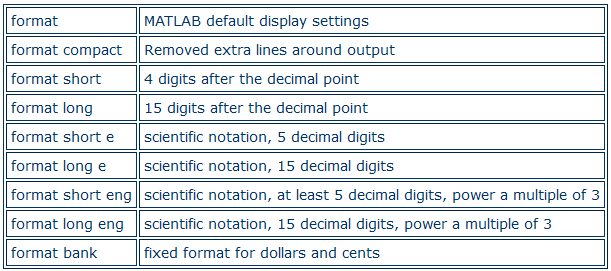

MATLAB may switch to another type of display in certain circumstances. 

    0.6/0.1

ans = 6.0000

    
    format long
    
    0.6/0.1

ans =    5.999999999999999


    
    format

    
    mod(4,pi);              % saved in ans variable
    rslt_6 = sqrt(val_3);   % Square root of val_3
    rslt_7 = abs(val_1);    % Absolute value of val_1
    rslt_8 = exp(2);        % Exponential : e^2


### 3- Complex Number

cmplx_1 = 2+3i;                   % complex data (also: 2+3j)

####     3.1- Functions Complex number 

    cmplx_2 = complex(val_1,val_2);     % cmplx_2 = -2.3 + pi*i
    real_1 = real(cmplx_1);             % returns 2
    imag_1 = imag(cmplx_1);             % returns 3
    abs_cmplx_1 = abs(cmplx_1);         % returns sqrt(2^2 + 3^2)
    angl_1 = angle(cmplx_1);            % returns atan2(3,2)
    z_bar = conj(cmplx_1);              % complex conjugate
    isreal(cmplx_2);                    % determine whether array is real
    

### 4- Character array and String

char_1 = 'Aerospace Engineering';        % character array (using single quote)
str_1 = "MATLAB Workshop";               % string (using double quote)
str_2 = "Welcome to the " + str_1;       % the summation can only use to concatenate strings (not character arrays)
str_3 = strcat(char_1," (",str_1, ")");  % concatenate strings and charachters (returns a string)
len_str = strlength(str_3);

disp('a' + 'b');

   195



char('a'-32);

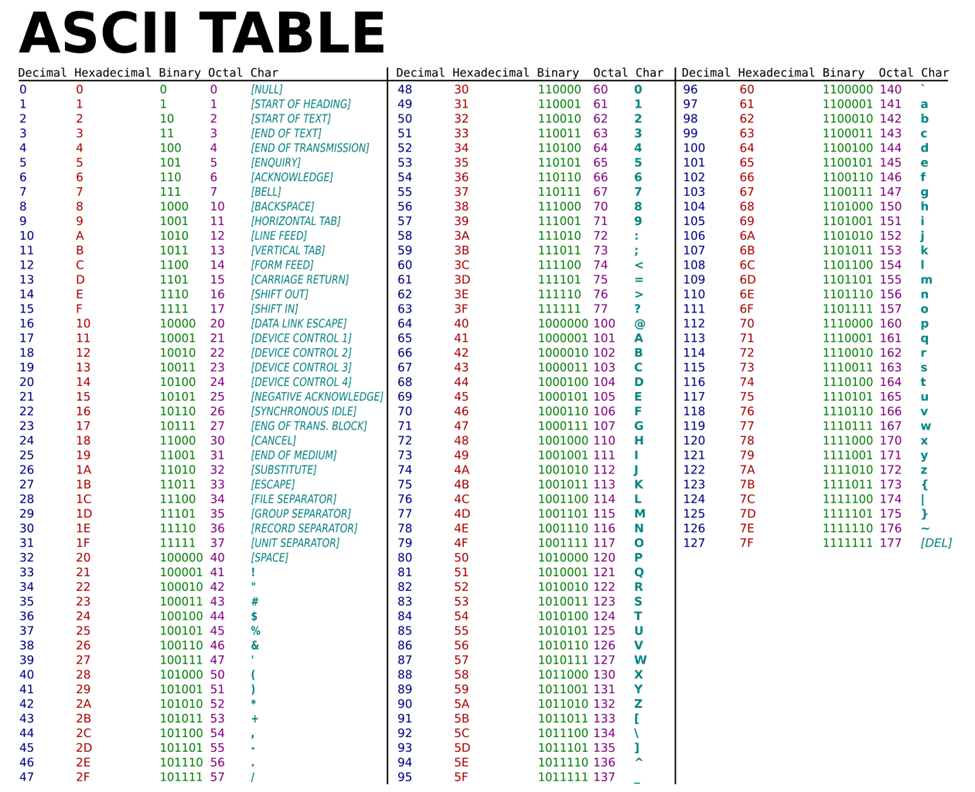

str_4 = "pi number is equal to: "+num2str(pi);

char_num = '-32.1';
str_num = "-32.1";
double(char_num);
double(str_num);
str2double(char_num);
isspace(str_4)

ans = 1×29 logical array
   0   0   1   0   0   0   0   0   0   1   0   0   1   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0   0


upper(str_4)

ans = "PI NUMBER IS EQUAL TO: 3.1416"

Converting Functions: str2double / str2func / str2num / str2angle / str2sym / str2mat

Type and Properties Functions: ischar / iscellstr / isstring / isStringScalar // strlength / isstrprop / isletter / isspace

Find and Replace Functions: contains / matches / count / endsWith / startsWith / strfind / sscanf // replace / replaceBetween / strrep

Match Patterns Functions: pattern // ...

Join and Split Functions: join / plus / split / splitlines / strjoin / strsplit / strtok / extract / extractAfter / extractBefore / extractBetween / **strcat**

Edit Functions: erase / eraseBetween / extract / extractAfter / extractBefore / extractBetween / insertAfter / insertBefore / pad / strip / **lower** / **upper** / reverse / deblank / strtrim / strjust

Compare Functions: matches / strcmp / strcmpi / strncmp / strncmpi

for more information look at the link below or simply search "characters and strings" in the help.

[https://www.mathworks.com/help/matlab/characters-and-strings.html](https://www.mathworks.com/help/matlab/characters-and-strings.html)

% str_4(6)            % comment this line to remove the error
new_char = convertStringsToChars(str_4);
new_char(6)

ans = 'm'

### 5- Vector and Matrix

#### 5.1- Vectors

horz_vec = [1, 2, -5, 7];              % also [1 2 -5 7]
vert_vec = [1; 2; -5; 7];

vec_1 = 1:0.2:6;                       % horizontal vector (= [1, 1.2, 1.4, ..., 6])  % The colon operator
vec_2 = linspace(1,6,26);              % horizontal vector (= [1, 1.2, 1.4, ..., 6])
vec_log = logspace(1,1e5,50);
vec_3 = transpose(vec_2);              % (also: vec_2') transpose the vector or matrix (=[1; 1.2; ...; 6])

vec_1(5)

ans = 1.8000

vec_1(1:6)

ans =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


vec_1(1:2:6)

ans =     1.0000    1.4000    1.8000


vec_1(6:end)

ans =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000



length(vec_1)

ans = 26


vec_4 = [1;2;0];
vec_5 = [-1;3;2];

disp(horz_vec + vert_vec)             % comment this line to eliminate the error

     2     3    -4     8
     3     4    -3     9
    -4    -3   -10     2
     8     9     2    14



disp(vec_4 + vec_5)

     0
     5
     2



disp(vec_4 - vec_5)

     2
    -1
    -2




disp(1./vec_5)                        % Element-wise operator

   -1.0000
    0.3333
    0.5000



disp(vec_4 .* vec_5)

    -1
     6
     0



disp(vec_4 ./ vec_5)

   -1.0000
    0.6667
         0



disp(vec_4 .^ vec_5)

     1
     8
     0




dot(vec_4, vec_5)                     % dot product

ans = 5

cross(vec_4,vec_5)                    % cross product

ans =      4
    -2
     5


norm(vec_4)

ans = 2.2361

diff(vec_4)                           % Differences (along columns)

ans =      1
    -2




[max_val, indx] = max(vec_5)          % min, mean: average or mean value, mode, std: standard deviation, var: variance

max_val = 3

indx = 2

#### 5.2- Matrices


mtrx_1 = [1, 2, 3; 4, 5, 6];           % 2D Matrix
mtrx_2 = [6 8 3;
          0 5 7;
          1 2 2];

mtrx_1(2,3)

ans = 6

mtrx_2(7)

ans = 3

mtrx_1(:,2)

ans =      2
     5


mtrx_1(3,:) = [-1, 0, 9];           % add a row
mtrx_1(1,:) = [];                   % remove a row

mtrx_3 = [mtrx_1 , mtrx_2(1:2,:)];  % horizontal concatenate
mtrx_4 = [mtrx_2 ; mtrx_1];         % vertical concatenate

size(mtrx_4)

ans =      5     3


size(mtrx_4,2)

ans = 3

length(mtrx_4)

ans = 5


inv(mtrx_2)

ans =    -0.2353   -0.5882    2.4118
    0.4118    0.5294   -2.4706
   -0.2941   -0.2353    1.7647


pinv(mtrx_1)

ans =     0.0991   -0.0726
    0.1075   -0.0655
    0.0110    0.1030


det(mtrx_2)

ans = 17.0000

eig(mtrx_2)

ans =     0.6229
    2.8707
    9.5064


rank(mtrx_2)

ans = 3

trace(mtrx_2)

ans = 13


sort(mtrx_2)

ans =      0     2     2
     1     5     3
     6     8     7


find(mtrx_2)

ans =      1
     3
     4
     5
     6
     7
     8
     9


find(mtrx_2 == 2)

ans =      6
     9


find(mtrx_2 > 5)

ans =      1
     4
     8



mtrx_3(:)

ans =      4
    -1
     5
     0
     6
     9
     6
     0
     8
     5



disp(mtrx_1(1:2,2:3) + mtrx_2(2:3,2:3))

    10    13
     2    11



disp(mtrx_1(1:2,2:3) - mtrx_2(2:3,2:3))

     0    -1
    -2     7



disp(mtrx_1 * mtrx_2)

    30    69    59
     3    10    15



disp(mtrx_1(1:2,2:3) .* mtrx_2(2:3,2:3))

    25    42
     0    18



disp(mtrx_2\vec_5)                          % = inv(mtrx_2)*vec_5

    3.2941
   -3.7647
    3.1176



disp(mtrx_1(1:2,2:3) ./ mtrx_2(2:3,2:3))

    1.0000    0.8571
         0    4.5000



disp(mtrx_1(1:2,2:3) .\ mtrx_2(2:3,2:3))

    1.0000    1.1667
       Inf    0.2222



disp(mtrx_2^2)

    39    94    80
     7    39    49
     8    22    21



disp(mtrx_2.^2)

    36    64     9
     0    25    49
     1     4     4




sum(mtrx_2)                         % Sum of elements (along columns)

ans =      7    15    12


sum(mtrx_2,2)                       % Sum of elements (along rows)

ans =     17
    12
     5


prod(mtrx_2)                        % Product of elements (along columns)

ans =      0    80    42



flip(mtrx_2)

ans =      1     2     2
     0     5     7
     6     8     3


fliplr(mtrx_2)

ans =      3     8     6
     7     5     0
     2     2     1


flipud(mtrx_2)

ans =      1     2     2
     0     5     7
     6     8     3



reshape(mtrx_1,[3, 2])

ans =      4     0
    -1     6
     5     9


sort(mtrx_2)

ans =      0     2     2
     1     5     3
     6     8     7



z_mx1 = zeros(3);                   % returns a square matrix of zeros
z_mx2 = zeros(3,2);
z_mx3 = zeros(3,1,2);

o_mx1 = ones(2);
o_mx2 = ones(2,3);


d_mx = 4

diag(mtrx_2)

ans =      6
     5
     2



rnd_mx1 = rand(2,2);                % Uniformly distributed random numbers in the interval (0,1)
rnd_mx2 = randn(2,2);               % Normally distributed random numbers
rnd_mx3 = randi([10 50],2,3);       % Uniformly distributed pseudorandom integers: generate 2*3 random integers from the uniform distribution between 10 and 50
rnd_mx4 = randperm(8,4);            % returns a row vector containing 4 unique integers selected randomly from 1 to 8

rng(1);                             % Control random number generator


- you can generate `N` random numbers in the interval (a,b) with the formula `r = a + (b-a).*rand(N,1)`

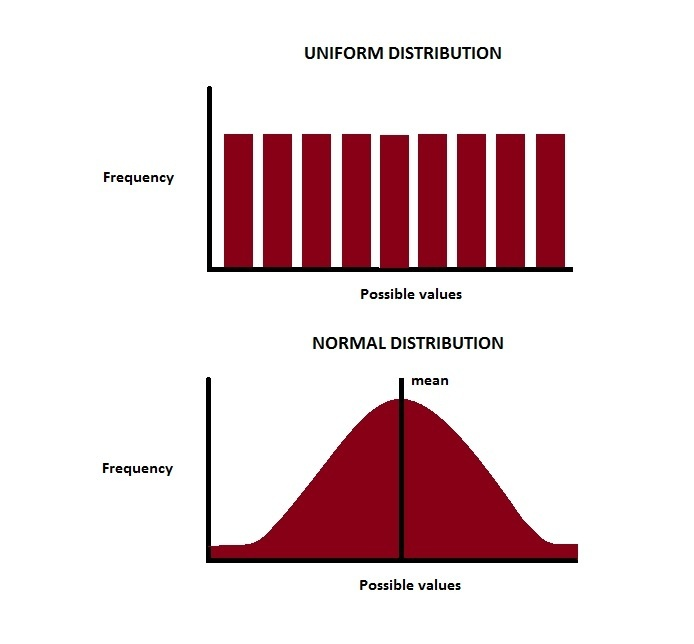


tril_mx = tril(ones(4));
triu_mx = triu(ones(4));

[mesh_x, mesh_y] = meshgrid(1:0.2:5,0:0.5:4);

% magic(4)

% diff()
[gx, gy] = gradient(mtrx_2)

### 6- Cell Array

A cell array is a data type with indexed data containers called cells, where each cell can contain any type of data. Cell arrays commonly contain either lists of text, combinations of text and numbers, or numeric arrays of different sizes. Refer to sets of cells by enclosing indices in smooth parentheses, (). Access the contents of cells by indexing with curly braces, {}.

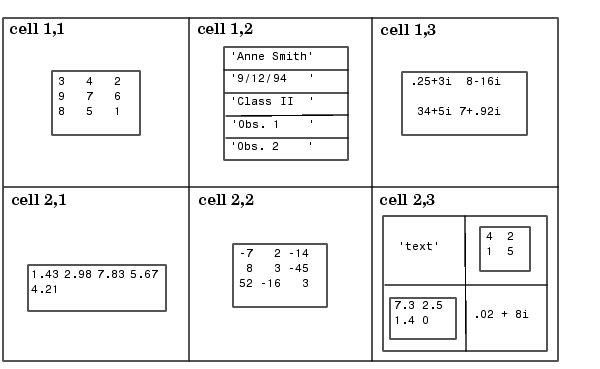

cel_arr = {1,2,3;'text',rand(5,10,2),{11; 22; 33}};
cel_arr(1,3)

ans = 1×1 cell array
    {[3]}


cel_arr{1,3}

ans = 3

### 7- Structure

A structure array is a data type that groups related data using data containers called** fields**. Each field can contain any type of data. Access data in a field using dot notation of the form structName.fieldName.

s = struct(field1,value1,...,fieldN,valueN)

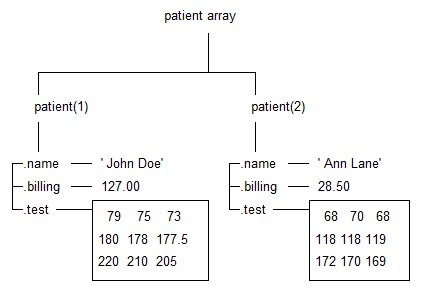

s = struct('x',{'a','b'},'y','c')

s = 1×2 struct array with fields:
    x
    y


s(2).x

ans = 'b'



patient(1).name = 'John Doe';
patient(1).billing = 127.00;
patient(1).test = [79, 75, 73; 180, 178, 177.5; 220, 210, 205];
patient(2).name = 'Ann Lane';
patient(2).billing = 28.50;
patient(2).test = [68, 70, 68; 118, 118, 119; 172, 170, 169];

### 8- Table

table arrays store **column-oriented** or **tabular data**, such as columns from a text file or spreadsheet. Tables store each piece of column-oriented data in a variable. Table variables can have different data types and sizes as long as all variables have the same number of rows. Table variables have names, just as the fields of a structure have names.

T = table(var1,var2,..., varN, `'Size',sz,'VariableTypes',varTypes,'VariableNames',varNames,'RowNames',rowNames)`

T = table([10;20;30],{'M';'F';'F'},'VariableNames',{'Age','Gender'},'RowNames',{'P1','P2','P3'})

T = 3×2 table
          Age    Gender
          ___    ______

    P1    10     {'M'} 
    P2    20     {'F'} 
    P3    30     {'F'} 


T.Age                           % returns vector or cell array

ans =     10
    20
    30


T.Age('P1')                     % returns value

ans = 10

T('P1','Age')                   % returns a table

ans = table
          Age
          ___

    P1    10 


T(4,:) = {25, 'M'};
T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Age'  'Gender'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {4×1 cell}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


T.Properties.Description = "Patient Data";
T.Properties.RowNames(4)={'P4'};
T({'P2','P4'},:)

ans = 2×2 table
          Age    Gender
          ___    ______

    P2    20     {'F'} 
    P4    25     {'M'} 



% help table
% readtable()

### 9- Symbol

syms x z
syms y real

### 10- datetime, date, hms

t_now = datetime('now');        % for more information, check the Help of the datetime function
datetime(1995,04,08)            % returns datetime variable (08-Apr-1995)

ans = datetime
   08-Apr-1995



[hr,min,sec] = hms(t_now);      % returns the hour, minute, and second values of the datetime or duration values in t as separate numeric arrays.

c_now = date;

% duration

### 10- Global Variable

global var_glob
var_glob = 2;

## MATLAB Built-in Functions


% who
% who x
% who x*
% whos
% whos x
% whos x*

% clc

% clear x
% clear all

% close
% close all

% disp()
% fprintf("The value is: %d",val)
% inp = input('Insert your number: ')

% tic, toc

% iskeyword('while')
% pretty(x/z);                       % Prettyprint symbolic expressions

% eval
eval("sind(30)")

ans = 0.5000

ans = 0.5000

### Arithmetic Functions

sin(pi/6)               % cos, tan, cot, sec, csc

ans = 0.5236

sind(30)                % cosd, tand, cotd, secd, cscd

ans = 30.0000

asin(0.5)               % acos, atan, acot, asec, acsc

ans = 0.2013

asind(0.5)              % acosd, atand, acotd, asecd, acscd
sinh(0.2)               % cosh, tanh, coth, sech, csch

ans = -0.7854

ans = 2.3562

atan(-1)

ans = -0.7854

atan2(3,-3)
atan2(-3,3)

ans = 0.5000

ans = 2

abs(-0.5)
sqrt(4)

ans = 2

ans = 4

log(exp(2))

ans = -2

log2(16)
log10(0.01)

erf(0.7)

### Discrete Math

ans =      2     3     7


factor(42)              % Prime factors (= 2 3 7)

ans = 120

factorial(5)            % = 1*2*3*4*5

ans = 6

gcd(30,42)              % greatest common divisor

ans = 42

lcm(6,14)               % lowest common multiple

ans = 3

mod(15,4)               % reminder after division

ans = 5

ceil(4.2)               % round toward positive infinity

ans = 4

floor(4.2)              % round toward negative infinity

ans = -2

fix(-2.5)               % round toward zero

ans = 4

round(4.2)              % round to nearest decimal or integer

ans = 5

round(4.8)


### Polynomials

poly([2, 3]);           % returns the coefficients of the polynomial whose roots are the elements of r, where r is a vector.
poly(mtrx_2);           % returns the n+1 coefficients of the characteristic polynomial of the matrix, det(λI – A), where A is an n-by-n matrix
roots([1 5 6]);         % returns the roots of the polynomial represented by p as a column vector.
polyval([1 2],3);       % polyval(p,x) evaluates the polynomial p at each point in x.
                        % 
                        
% polyint(p,k);         % returns the integral of the polynomial represented by the coefficients in p using a constant of integration k.
% polyder(p);
% ppval
% mkpp
% unmkpp

Example: Evaluate the difinite integral:


$$I=\int_{-1}^3 \left(3x^4 -4x^2 +10x-25\right)\textrm{dx}$$


co_p = [3 0 -4 10 -25];
co_ip = polyint(p);
I = diff(polyval(co_ip,[-1 3]));

n smaller 10


## Control Structures in MATLAB

### 1- if, elseif, else

n = input("Enter a value:");

n = 1

if n<10
    disp('n smaller 10')
elseif n<20
    disp('n between 10 and 20')
else
    disp('n larger than 20')
end % control structures terminate with end


% 

positive one


% if 0.6/0.1 - 6 == 0
%     true
% else
%     false

Hi
Hi
Hi
Hi


% end

### 2- switch case

n = input('Enter a number: ')
switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case {1,2,3} %check three cases together
        disp('positive one')
    otherwise
        disp('other value')
end

### 3- for loop

for i = 1:4
    disp('Hi');
end

% break                 % exit the current loop (combine with if)
% continue              % go to next iteration (combine with if)

### 4- while loop

n = 1;
nFactorial = 1;
while nFactorial < 1e100
    n = n + 1;
    nFactorial = nFactorial * n;
end


- MATLAB 

### 5- try, catch

clear all
try
    c = a+b;
catch 
    c = 10;
end

## MATLAB Functions

### 1- anonymous function 

fun_1 = @(x,y) x.^2+y.^2;
fun_2 = @(x) [x.^2 x.^3];

out_1 = fun_1(1,2);
out_2 = fun_2(-3);



#### 1.1- Numerical Integration

% integral()


$$\int_0^{\infty } x^5 e^{-x} \;\sin \left(x\right)\;\textrm{dx}$$


fun = @(x) x.^5.*exp(-x).*sin(x);
q = integral(fun,0,Inf)

% integral2()



$$f\left(x,y\right)={\textrm{ax}}^2 +{\textrm{by}}^2$$


fun = @(x,y,a,b) a*x.^2 + b*y.^2;
a = 3;
b = 5;
q = integral2(@(x,y) fun(x,y,a,b),0,5,-5,0,'Method','iterated','AbsTol',0,'RelTol',1e-10)



$$\int_0^{2\pi } \int_0^3 r\;\textrm{drd}\theta$$


fun = @(r,th) r;
aera = integral2(fun,0,3,0,2*pi);

% integral3()
% trapz()

### 2- Function

function [out1, out2, ..., outN] = functionName(in1, in2, ..., inN)

    statements;

end

% save the following function as a separate m-file

function c = addme(a,b)
% ADDME  Add two values together.
%   C = ADDME(A) adds A to itself.
%
%   C = ADDME(A,B) adds A and B together.
%
%   See also SUM, PLUS.

switch nargin
    case 2
        c = a + b;
    case 1
        c = a + a;
    otherwise
        error('you should insert at least one value');
end
end


- nargin

- description

- error

## Plot

clear
clc

x = linspace(-5,5,100);
y = x .^ 2;

plot(x,y)

xlabel('x [m]');
ylabel('y [m]');
title('y-x plot');      % add title to the plot
legend('Height');       % add legend to the plot
grid on
box on                  % border of the plot (box off)
% axis off                % axis visibility (axis on)
xlim([-2 3])
ylim([-1 10])
% axis square


plot(x(1:5:end), 3*sqrt(abs(x(1:5:end))),'Color','k','LineWidth',2,'LineStyle','--','Marker',"o","MarkerFaceColor",'r',"MarkerEdgeColor",'b')
xlabel('\bf\fontname{Times New Roman}\fontsize{20} X (m)');
% hold on
% figure
% subplot


% figureHandle = gcf;
% figureHandle.ToolBar = 'none';

% ax = gca;
% ax.FontSize = 12;

% set(gca, 'xScale', 'log')
% set(gca, 'YScale', 'linear')
% set(gca,'FontSize',12,'FontName','Times New Roman','FontWeight','bold');
% set(findall(figureHandle,'type','text'),'FontName','Times New Roman','fontSize',16,'fontWeight','bold')
% get
% text(x,y,str)
% pause

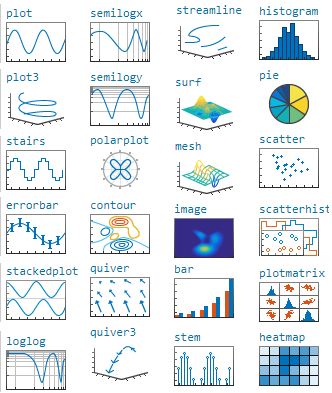

#### symbolic function plot

clear all
syms x
sym_fun = sin(x)
ezplot(sym_fun, [-pi 2*pi]);

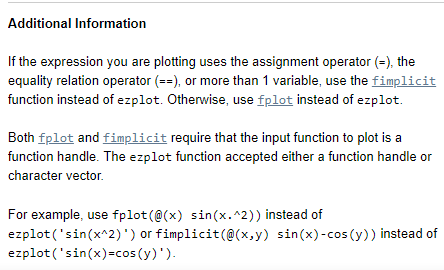

clear all
x = -2:0.1:2;
y = -2:0.1:2;
fun_3D = x.^2 + y.^2;
plot3(x,y,fun_3D)


#### surf

[X, Y] = meshgrid(x,y);
z = X.^2 + Y.^2;
surf(X,Y,z)

#### mesh plot

mesh(x,y,z)

#### contour

contour(X,Y,z)

#### quiver

clear all
spacing = 0.2;
[X,Y] = meshgrid(-2:spacing:2);
Z = X.*exp(-X.^2 - Y.^2);
[DX,DY] = gradient(Z,spacing);
quiver(X,Y,DX,DY)
hold on
contour(X,Y,Z)
axis equal
hold off

### Graphics Object Properties

plt = plot(1:10,1:10);


### Animation

x=0:0.1:8;
y=sin(x);

for i = 1 :length(x)
    p1 = plot(x(1:i),y(1:i));
    xlim([0 8])
    ylim([-1 1])
    pause(0.1)
end


for i = 1 :length(x)
    p1 = plot(x(i),y(i),'o');
    hold on
    F(i)=getframe;
end
movie(F,8) 



frame = struct('cdata',[],'colormap',[]);
v = VideoWriter('test.avi');
open(v);

for i = 1:10
    plot()
    frame = getframe(gcf);
    writeVideo(v,frame);
end
close(v)

### Davinci Arrow

davinci( 'arrow', 'X',             [0 15], ...
                      'Y',             [0  0], ...
                      'Head.Length',        0.8, ...
                      'Head.Width',         0.6, ...
                      'Head.Sweep',         0.1, ...
                      'Color',        'k', ...
                      'LineWidth',          0.1 );


### Child Plot

f0 = 10000;
t = 0:(1/f0)/1000:((1/f0)*2);
y = 5*sin(2*pi*f0*t) + rand(size(t));
plot(t*1000, y);
hold on;

% creating the zoom-in inset
ax=axes;
set(ax,'units','normalized','position',[0.2,0.2,0.2,0.2])
box(ax,'on')
plot(t*1000, y,'r','LineWidth',2,'parent',ax)
set(ax,'xlim',[0,0.01],'ylim',[0,4])

### MagInset

h1 = figure;
title('Single Axes MagInset Example');
hold on;
f0 = 10000;
t = 0:(1/f0)/1000:((1/f0)*2);
y = 5*sin(2*pi*f0*t) + rand(size(t));
plot(t*1000, y);
grid on;
xlabel('Time (ms)');
ylabel('Amplitude (V)');
% It is important to set the figure size and limits BEFORE running
% MagInset!
xlim([t(1) t(end)]*1000);
ylim([-6 10]);
set(h1, 'Position',[105   647   560   420]);

% Once happy with your figure, add an inset:
MagInset(h1, -1, [0.04 0.045 1 4], [0.05 0.09 5.5 9], {'NW','NW';'SE','SE'});

## Fitting and Interpolation

### 1- polyfit

% [p,S,mu] = polyfit(x,y,n)
% returns the coefficients for a polynomial p(x) of degree n that is a best fit (in a least-squares sense) for the data in y.
% also returns a structure S that can be used as an input to polyval to obtain error estimates.
% also returns mu, which is a two-element vector with centering and scaling
% values. mu(1) is mean(x), and mu(2) is std(x).

x = 1:50; 
y = -0.3*x + 2*randn(1,50); 
p = polyfit(x,y,1);
f = polyval(p,x); 
plot(x,y,'o',x,f,'-') 
legend('data','linear fit') 



### 2- fit

t = (0:0.5:5)';
y = t.^2 + rand(size(t));
op = fitoptions('Method','NonlinearLeastSquares',...
               'Lower',[0,0],...
               'Upper',[Inf,max(t)],...
               'StartPoint',[1 1]);
tp = fittype('a*(x-b)^n','problem','n','options',op);
[curve,gof] = fit(t,y,tp,'problem',2)

plot(t,y,'*r')
hold on
plot(curve,'k')


### 3- Interpolation

% interp1
% interp2
% interp3

x = (datetime(2016,1,1):hours(4):datetime(2016,1,2))';
x.Format = 'MMM dd, HH:mm';
T = [31 25 24 41 43 33 31]';
WeatherData = table(x,T,'VariableNames',{'Time','Temperature'})
plot(WeatherData.Time, WeatherData.Temperature, 'o')
xq = (datetime(2016,1,1):minutes(1):datetime(2016,1,2))';
V = interp1(WeatherData.Time, WeatherData.Temperature, xq, 'spline');
hold on
plot(xq,V,'r')

% pchip
% spline
% makima

x = -3:3; 
y = [-1 -1 -1 0 1 1 1]; 
xq1 = -3:.01:3;
p = pchip(x,y,xq1);
s = spline(x,y,xq1);
m = makima(x,y,xq1);
plot(x,y,'o',xq1,p,'-',xq1,s,'-.',xq1,m,'--')
legend('Sample Points','pchip','spline','makima','Location','SouthEast')

## Working with Files

### 1- Excel files

% out = xlsread(filename,sheet,xlRange);
Data = xlsread('test.xlsx',1,'B2:C5');

% xlswrite(filename,A,sheet,xlRange)
xlswrite('new.xlsx',Data);


### 2- Text Files

A = magic(3);

% fprintf(fileID,formatSpec,A1,...,An)
fid1=fopen("new.txt","w");
fprintf(fid1,'%3d \t %3d \t %3d \n',A);
fclose(fid1);

% A = fscanf(fileID,formatSpec,sizeA)
fid2 = fopen("new.txt","r")
B = fscanf(fid2,'%3d \t %3d \t %3d \n',[3 Inf]);
fclose(fid2);


### 3- Image Files

img = imread();
image(img)


Z = 10 + peaks;
surf(Z)
hold on 
image(Z,'CDataMapping','scaled')

### 4- Other ways

% readmatrix()
% readcell()
% readtable()

## Linear and Nonlinear Equations

% fsolve(): Solve system of nonlinear equations
% [x,fval,exitflag,output] = fsolve(fun,x0,options)


$$\begin{array}{l}
2x-y=e^{-x} \\
-x+2y=e^{-y} 
\end{array}$$



F = @(x) [2*x(1) - x(2) - exp(-x(1));
         -x(1) + 2*x(2) - exp(-x(2))];
x0 = [-5;-5];
options = optimoptions('fsolve','Display','iter');
[x,fval,exitflag] = fsolve(F,x0,options)

% fzero(): Root of nonlinear function
% [x,fval,exitflag,output] = fzero(fun,x0,options)

function y = myFun(x)
y = x.^3 - 2*x - 5;

x0 = 2; % initial point
z = fzero(@myFun,x0);

% solve()
% [sol,fval,exitflag,output,lambda] = solve(prob,x0)

solve the nonlinear system of equations


$$\begin{array}{l}
\exp \left(-\exp \left(-\left(x+y\right)\right)\right)=y\left(1+x^2 \right)\\
\textrm{xcos}\left(y\right)+\textrm{ysin}\left(x\right)=\frac{1}{2}
\end{array}$$


x = optimvar('x',2);
eq1 = exp(-exp(-(x(1) + x(2)))) == x(2)*(1 + x(1)^2);
eq2 = x(1)*cos(x(2)) + x(2)*sin(x(1)) == 1/2;
prob = eqnproblem;
prob.Equations.eq1 = eq1;
prob.Equations.eq2 = eq2;
show(prob)
x0.x = [0 0];
[sol,fval,exitflag] = solve(prob,x0);
disp(sol.x(1))
disp(sol.x(2))

- optimvar creates optimization variables

- `x = optimvar(name,n,'Type'``,``'integer'``,``'LowerBound'``,0,``'UpperBound'``,1)`

## Optimization

% fminbnd is a one-dimensional minimizer that finds a minimum for a problem
% specified by: min f(x) such that x_1 < x < x_2
% [x,fval,exitflag,output] = fminbnd(fun,x1,x2,options)
% options = optimset(,'MaxIter',100,'Display','iter','PlotFcns',@optimplotfval);

% save the following function as a separate m-file
function y=myfun(x)
    y=x^2;
end

x = fminbnd(@myfun,-10,10);

% fminunc: Find minimum of unconstrained multivariable function
% [x,fval,exitflag,output,grad,hessian] = fminunc(fun,x0,options)



$$f\left(x\right)=3x^2 +2\textrm{xy}+y^2 -4x+5y$$



fun = @(x)3*x(1)^2 + 2*x(1)*x(2) + x(2)^2 - 4*x(1) + 5*x(2);
x0 = [1,1];
[x,fval] = fminunc(fun,x0);



$$\begin{array}{l}
f\left(x\right)=100{\left(y-x^2 \right)}^2 +{\left(1-x\right)}^2 \\
\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
-400\left(y-x^2 \right)x-2\left(1-x\right)\\
200\left(y-x^2 \right)
\end{array}\right\rbrack 
\end{array}$$


% save the following function as a separate m-file
function [f,g] = myfun(x)
% Calculate objective f
f = 100*(x(2) - x(1)^2)^2 + (1-x(1))^2;

if nargout > 1 % gradient required
    g = [-400*(x(2)-x(1)^2)*x(1)-2*(1-x(1));
        200*(x(2)-x(1)^2)];
end
end

options = optimoptions('fminunc','Algorithm','trust-region','SpecifyObjectiveGradient',true);
problem.options = options;
problem.x0 = [-1,2];
problem.objective = @myfun;
problem.solver = 'fminunc';
x = fminunc(problem);

% fmincon: Find minimum of constrained nonlinear multivariable function
% [x,fval,exitflag,output,lambda,grad,hessian] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)



$$\min_x \;f\left(x\right)\;\textrm{such}\;\textrm{that}:\;c\left(x\right)\le 0,\;\;\;\;\textrm{ceq}\left(x\right)=0,\;\;\;A\ldotp x\le b,\;\;\;\textrm{Aeq}\ldotp x=\textrm{beq},\;\;\;\textrm{lb}\le x\le \textrm{ub}$$


fun = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
x0 = [0.5,0];
A = [1,2];                  % x+2y <= 1
b = 1;
Aeq = [2,1];                % 2x+y = 1
beq = 1;
x = fmincon(fun,x0,A,b,Aeq,beq);

fun = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2;

% save the following function as a separate m-file
function [c,ceq] = circlecon(x)
c = (x(1)-1/3)^2 + (x(2)-1/3)^2 - (1/3)^2;
ceq = [];
end

lb = [0,0.2];
ub = [0.5,0.8];
x0 = [1/4,1/4];
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = @circlecon;
x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon);

% solve

x = optimvar('x');
y = optimvar('y');
prob = optimproblem;
prob.Objective = -x - y/3;

prob.Constraints.cons1 = x + y <= 2;
prob.Constraints.cons2 = x + y/4 <= 1;
prob.Constraints.cons3 = x - y <= 2;
prob.Constraints.cons4 = x/4 + y >= -1;
prob.Constraints.cons5 = x + y >= 1;
prob.Constraints.cons6 = -x + y <= 2;
x0.x = 0;
x0.y = 0;

sol = solve(prob, x0);

% fminsearch: Find minimum of unconstrained multivariable function using derivative-free method
% lsqnonneg: Solve nonnegative linear least-squares problem
% fzero
% optimget
% optimset

## Differential Equations

### 1- Ordinary Differential Equation

% ode45: Solve nonstiff differential equations — medium order method
% [t,y,te,ye,ie] = ode45(odefun,tspan,y0,options)



$$y^{\left(4\right)} =f\left(t,y^{\prime } ,{y^{\prime } }^{\prime } ,{{y^{\prime } }^{\prime } }^{\prime } \right)$$


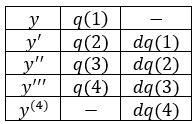


$$\begin{array}{l}
\textrm{dq}\left(1\right)=q\left(2\right)\\
\textrm{dq}\left(2\right)=q\left(3\right)\\
\textrm{dq}\left(3\right)=q\left(4\right)\\
\textrm{dq}\left(4\right)=f\left(x,q\left(1\right),q\left(2\right),q\left(3\right),q\left(4\right)\right)
\end{array}$$


example: Mass - Spring - Damper


$$m\ddot{x} +c\dot{x} +\textrm{kx}=f\left(t\right)$$


x    q(1)        -

x'    q(2)       dq(1)

x''    -            dq(2)

% save the following function as a separate m-file
function dq=myodefun(t,q,m,c,k,in)
    dq = zeros(2,1);
    fi = eval(in);
    dq(1)=q(2);
    dq(2)=(fi-k*q(1)-c*q(2))/m;
end

m=5;c=0.5;k=20;
t_i = 0; t_f = 10; t_step = 0.1;
t_span = t_i:t_step:t_f;
in = 'sin(t)';
x_0 = 0; v_0 = 0;
[t,x]=ode45(@(t,q) myodefun(t,q,m,c,k,in),t_span,[x_0 v_0]);
figure(1)
subplot(1,2,1)
plot(t,x(:,1))
ylabel('x [m]')
xlabel('time [s]')
grid on
hold on
subplot(1,2,2)
plot(t,x(:,2))
ylabel('v [m/s]')
xlabel('time [s]')
grid on
figure(2)
plot(x(:,2),x(:,1))
title('Phase Portrait')
xlabel('$x$','interpreter','latex')
ylabel('$\dot{x}$','interpreter','latex')

### 2- Boundary Value Problem

% bvp4c: Solve boundary value problem — fourth-order method
% sol = bvp4c(odefun,bcfun,solinit,options)



$$\begin{array}{l}
{y^{\prime } }^{\prime } +3y^{\prime } +6y=5\\
y\left(1\right)=3\\
y\left(3\right)+2y^{\prime } \left(3\right)=5\\
x\in \left\lbrack 1,3\right\rbrack 
\end{array}$$


% state space variables
% q(1) = y(x)
% q(2) = y'(x)

% state space equations
% dq(1) = q(2)
% dq(2) = 5 - 3q(2) - 6q(1)

% boundary condition
% @ x_L = 1 : q(1)-3 = 0
% @ x_R = 3 : q(1) + 2q(2) - 5 = 0

guess = [0 0];
init=bvpinit(linspace(1,3,10),guess);
sol=bvp4c(@bvp4ode,@bvp4bc,init);       % If you need to pass a variable to functions, use the format explained in ode45
x=linspace(1,3,100);
BS=deval(sol,x);
plot(x,BS(1,:))

% save the following function as a separate m-file
function bc=bvp4bc(yL,yR)
bc=[yL(1)-3 ; yR(1)+2*yR(2)-5];
end

% save the following function as a separate m-file
function dq=bvp4ode(x,q)
dq=zeros(2,1);
dq(1) = q(2);
dq(2) = 5-3*q(2)-6*q(1);
end

### 3- Partial Differential Equation

% pdepe: Solve 1-D parabolic and elliptic PDEs
% pdeval: Interpolate numerical solution of PDE


### 4- CFD: Finite Difference

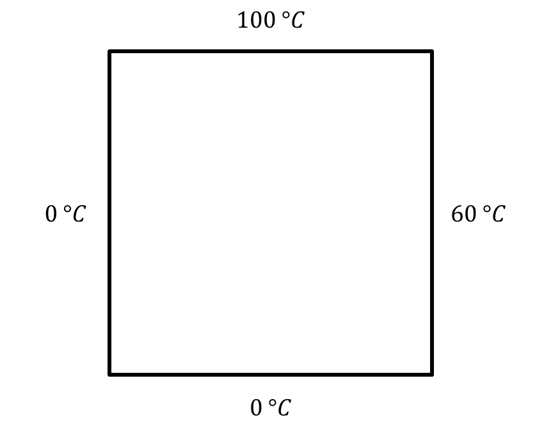


$$\frac{\partial^2 }{\partial x^2 }T+\frac{\partial^2 }{\partial y^2 }T=0$$


Nx = 10;
Ny = 10;
T = zeros(Nx, Ny);
T(1,:) = 100;
T(:,1) = 0;
T(end,:) = 0;
T(:,end) = 60;
Told = T;
e_max = 1e-5;
i_max = 1000;
iter = 0;
err = Inf;


Function definitions in a script must appear at the end of the file.
Move all statements after the "addme" function definition to before the first local function definition.

while err > e_max && iter < i_max
    for i = 2 : Nx-1
        for j = 2 : Ny-1
            T(i,j) = 0.25*(T(i-1,j) + T(i+1,j) + T(i,j-1) + T(i,j+1));
            err = norm(T-Told);
            Told = T;
        end
    end
    iter = iter + 1;
end

disp(err)
disp(iter)
z = flipud(T);
contourf(z,'linecolor','none')
colorbar
hold on
[gx, gy] = gradient(z);
quiver(-gx, -gy, 'color', 'r');

## Symbolic Coding

syms x y real
syms z

f1 = x^2 - 5*y + 6;
dif_f = diff(f1,x);
f2 = x^2 - 5*x + 6;
pretty(f2); 
int_f = integral(f2,0,5);

eq = a*y + b == c;
solve(eq,y)

% subs
f3 = x^2 + 3;
subs(f3,x,2)                         % substituting x with 2 in f (=f(2))


## MATLAB Toolbox - curve fitting

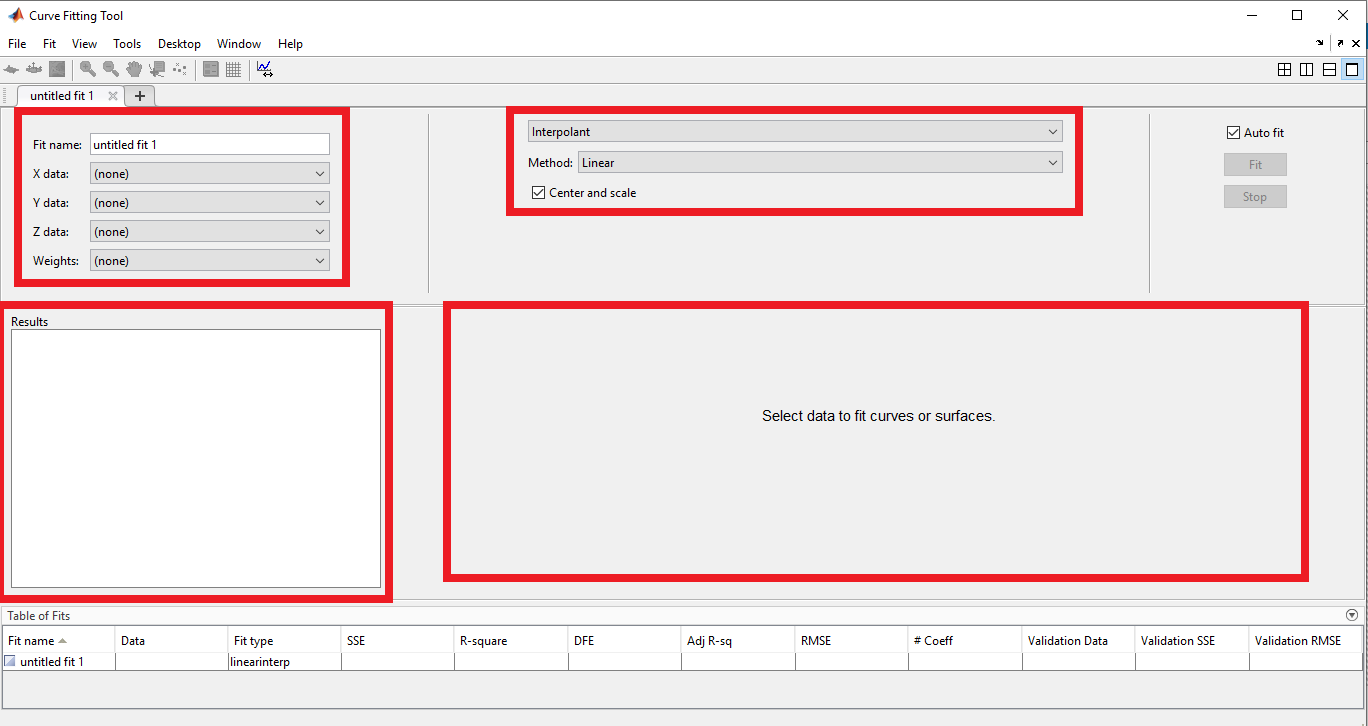

## Simulink